# State constrained optimal control : an exterior penalty approach

[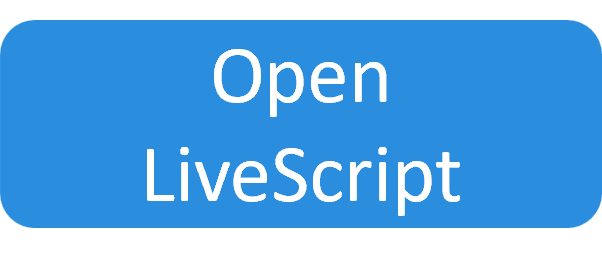](matlab:dxdzds.file='stateConstraint';dxdzds.outFile=fullfile(pwd,dxdzds.file);copyfile(which(['user_' dxdzds.file]),[dxdzds.outFile '.mlx']);open(dxdzds.outFile);clear dxdzds;)

## Considered problem

### Original problem

The criterion to be minimized over $\left\lbrack 0,T\right\rbrack$, with $T=10s$, is :

$J=\int_0^T \left({u\left(t\right)}^2 +{x\left(t\right)}^2 \right)\textrm{dt}$                                       (1)

The system dynamics is :

$\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}={x\left(t\right)}^2 -u\left(t\right)$                                             (2)

The control constraint is :

$u\left(t\right)\in \left\lbrack \underline{u} ,\bar{u} \right\rbrack$                                                        (3)

The state constraint is :

$x\left(t\right)\ge a$                                                                (4)

The boundary condition is :

$x\left(0\right)=x_0$;$x\left(T\right)=x_T$                                             (5)

Numerical values : $x_0 =1$, $x_T =1$, $a=0\ldotp 85$, $\underline{u} =-5$ and $\bar{u} =5$.

### Exterior penalty

Dealing with state constraint is in general very difficult without additionnal information on the solution structure.

On approach is to replace the state constraint (4) by an extrior penalty $P\left(x\right)$ such as $P\left(x\right)=0$ when $x\left(t\right)\ge a$ and $P\left(x\right)\to +\infty$ when $x\left(t\right)\ll a$.


$$P\left(x\right)=\Gamma_a \left(x\left(t\right)\right){\left(x\left(t\right)-a\right)}^2$$


with $\Gamma_a \left(x\right)=$$\left\lbrace \begin{array}{l}
1\;\;\;\;\;\textrm{if}\;x\left(t\right)<a\\
0\;\;\;\;\;\textrm{otherwise}
\end{array}\right.$                                               (6)

The resulting penalized problem is :

$J_{\rho } =\int_0^T \left({u\left(t\right)}^2 +{x\left(t\right)}^2 \right)+\frac{1}{\rho }P\left(x\right)\textrm{dt}$                                        (7)

$\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}={x\left(t\right)}^2 -u\left(t\right)$                                                             (8)

$u\left(t\right)\in \left\lbrack \underline{u} ,\bar{u} \right\rbrack$                                                                        (9)

$x\left(0\right)=x_0$;$x\left(T\right)=x_T$                                                           (10)

It is expected tha the solution of the penalized problem (6)-(10) converges toward the solution of the state constrained problem (1)-(5) when $\rho \to 0^+$.

## PMP for the penalized problem

Let us denote $p\left(t\right)$ the co-state, the Hamiltonian associated with the penalized problem is:

$H\left(x,u,p\right)=$$\left({u\left(t\right)}^2 +{x\left(t\right)}^2 \right)+\frac{1}{\rho }\Gamma_a \left(x\left(t\right)\right){\left(x\left(t\right)-a\right)}^2 +p\left(t\right)\left({x\left(t\right)}^2 -u\left(t\right)\right)$    (11)

This Hamiltonian being quadratic in the control, the unconstrained optimal control $u_c$ is :


$$\frac{\partial H\left(x,u,p\right)}{\partial u}=0\iff u_c \left(t\right)=\frac{1}{2}p\left(t\right)$$


The optimal control is 


$$u_c \left(t\right)=\min \left(\bar{u} ,\max \left(\underline{u} ,\frac{1}{2}p\left(t\right)\right)\right)$$


The optimal co-state dynamics is:


$$\dot{p} \left(t\right)=-\frac{\partial H}{\partial x}=-2x\left(t\right)-2p\left(t\right)x\left(t\right)+\frac{2}{\rho }\Gamma_a \left(x\left(t\right)\right)\left(x\left(t\right)-a\right)$$


Finally, considering $Y\left(t\right)={\left\lbrack \begin{array}{cc}
x\left(t\right) & p\left(t\right)
\end{array}\right\rbrack }^T$, the Boundary Value Problem to be solved is:

$\frac{\textrm{dY}\left(t\right)}{\textrm{dt}}=\left(\begin{array}{c}
{x\left(t\right)}^2 -\min \left(\bar{u} ,\max \left(\underline{u} ,-\frac{1}{2}p\left(t\right)\right)\right)\\
-2x\left(t\right)-2p\left(t\right)x\left(t\right)+\frac{1}{\rho {\left(a-x\right)}^2 }
\end{array}\right)$                                                                    (12)

$x\left(0\right)=x_0$;$x\left(T\right)=x_T$                                                                                                          (13)

The corresponding code is given here

## Problem solving using continuation procedure

% Problem parameters
clearvars;close all; clc
T=2;x0=1;xT=1;umin=-1.5;umax=1.5;

We use a constant solution $x\left(t\right)=x_0$ andd $p\left(t\right)=0$ as an initial guess.

% Initialization of the BVP at steadystate
nInit=10;
solInit.x=linspace(0,T,nInit);
solInit.y=repmat([x0;0],[1 nInit]);

We now fix the values of $x_0$, $x_T$, $a$, $\underline{u}$ and $\bar{u}$.

fixedParams.a=0.85;
fixedParams.x0=x0;fixedParams.xT=xT;
fixedParams.umin=umin;fixedParams.umax=umax;

We are going to apply a continuation procedure on $\rho :$

paramStart.rho=1e5;paramEnd.rho=1e-15;

We can now define the logarithmic scheduler to be used.

scheduler=logScheduler(paramStart,paramEnd, fixedParams=fixedParams,...
    initialDelta=0.9,beta=1.2*0+10,deltaMin=1e-10,lambdaMin=1e-10);

We can now define the problem to be solved at each iteration of the continuation procedure. It consists in the boundary value problem (12) & (13). This BVP will be solved using Matlab `bvp2p` solver.

We also need several functions (available at the bottom of this document):

- generateFodeFcn : to generate a handle to the BVP dynamics that uses the current value of the continuation parameters

- generateBCFcn : to generate a handle to the BVP boundary conditions that uses the current value of the continuation parameters

The problem to be solved by the continuation procedure can now be defined. 

bvpOpt=bvpset('RelTol',1e-6,'AbsTol',1e-9,'Nmax',50000);
problem=bvp2p(@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

Now we can perform the continuation procedure to progressively decrease the value of $\rho$ .

 We use a custom function `plotFigFcn` to plot the solution at every iteration and we request to modify the solution provided by the BVP solver.  We also use `preIterPrintFcn` to display the value of `a` and `rho` at every iteration.

plotFigFcn : to plot the solution obtained at every iteration

modifySolutionFcn : function to add the control `u` and the Hamiltonian `H` to the solution.

`preIterPrintFcn``: `funciton to display the value of `a` and `rho` at every iteration 

Checking initial solution feasability
Done (initial solution is feasible)
Iter : 001 Lambda : 1.0000e+00 delta : 9.00e-01 a=0.85 rho=1.00e+05
Iter : 002 Lambda : 9.0000e-02 delta : 9.00e-02 a=0.85 rho=9.00e+03
Iter : 003 Lambda : 8.1000e-04 delta : 9.00e-03 a=0.85 rho=8.10e+01
Iter : 004 Lambda : 7.2900e-07 delta : 9.00e-04 a=0.85 rho=7.29e-02
Iter : 005 Lambda : 6.5610e-11 delta : 9.00e-05 a=0.85 rho=6.56e-06


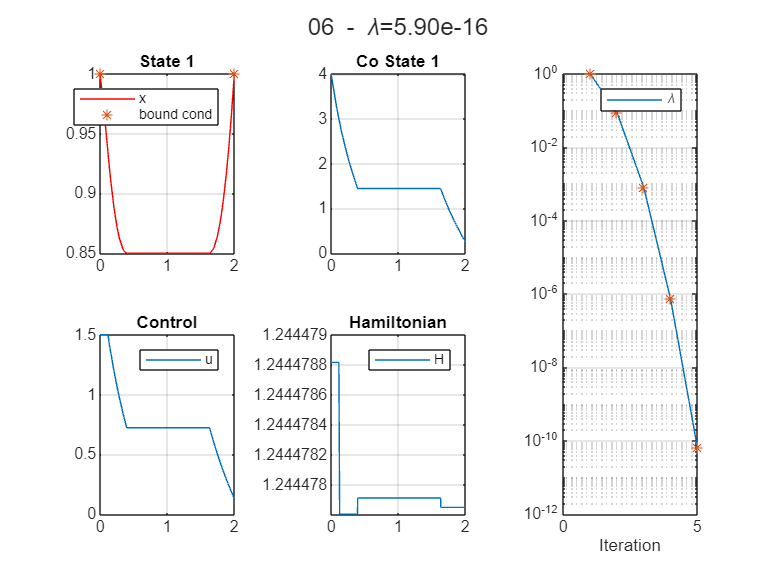

cont=continuationProcedure(problem,scheduler,solInit, ...
    "plotFigFcn",@plotFigFcn,...
    "modifySolutionFcn",@modifySolutionFcn,...
    "preIterPrintFcn",@preIterPrintFcn);
cont.run;

fprintf('done')

done

### Function related to the BVP to be solved

This code allows to compute the solution of the Hamiltonian minimization

function [u,H]=computeControlHamiltonian(x,p,rho,a,umin,umax)
% Compute the optimal control u and the hamiltonian (if requested)
u=max(umin,min(umax,p/2));
if nargout==2
    % Only compute the Hamiltonian when requested
    H=(u.^2+x.^2) + p.*(x.^2-u) + (x<a).*(x-a).^2/rho;
end
end

The BVP dynamics is given here. It depends on several parameters  whose value wil be passed by the `generateFode` function.

function dydt=fdyn(y,rho,a,umin,umax)
% Compute the BVP to be solved : dYdt=[dxdt;dpdt]
x=y(1);p=y(2);
% Compute the control
[u,~]=computeControlHamiltonian(x,p,rho,a,umin,umax);
% Compute state & co-state dynamics
dxdt  = x^2-u;
dpdt=-2*x -2*p*x -2*(x<a).*(x-a)/rho;
dydt=[dxdt;dpdt];
end

This is the code for the boundary value problem.

function res=bcfun(ya,yb,x0,xT)
% Boundary condition to be canceled
res=[ya(1)-x0;
    yb(1)-xT];
end

## Functions specific to the continuation procedure

- **generateFodeFcn**

`generateFodeFcn` has to provide a handle to the bvp dynamics according to the parameter values (manipulated or not by the continuation procedure). Here the `rho` parameter will be updated by the continuation procedure while `a`, `umin` and `umax` are fixed. 

function fode=generateFodeFcn(continuationParams,fixedParams)
% retrieve a handle to the ode function with the current parameters
% values
retrieveContinuationParameters({continuationParams,fixedParams});
fode=@(t,y) fdyn(y,rho,a,umin,umax);
end

- `generateBCFcn`

`generateBCFcn` has to provide a handle to the bvp boundary conditions according to the parameter values (manipulated or not by the continuation procedure).  In this example `x0` and `xT` remains fixed.

function bcond=generateBCFcn(continuationParams,fixedParams)
% retrieve a handle to the boundary condition function with the
% current parameters values
retrieveContinuationParameters({continuationParams,fixedParams});
bcond=@(ya,yb) bcfun(ya,yb,x0,xT);
end

- `modifySolutionFcn`

In the optimal control problem, the controls $u$ is computed but it remains an internal data usined internaly within the BVP dynamics `fdyn`. As we would like to display the controls signal, we need to add it to the solution structure. We also compute the Hamiltonian value in the same way. 

function sol=modifySolutionFcn(sol,iterSuccess,continuationParams,fixedParams)
if iterSuccess
    retrieveContinuationParameters({continuationParams,fixedParams});
    x=sol.y(1,:);p=sol.y(2,:);
    % Add the control signal u to the solution
    [sol.u,sol.H]=computeControlHamiltonian(x,p,rho,a,umin,umax);
end
end

- `plotFigFcn`

The `plotFigFcn` receive an `iterartiveDisplay` object that allows quick update of the graphics. It is advised to use it. The continuation procedure will call the `id.newIteration` and the `id.finalIteration` methods.

Alternatively, you may use your own code. The `plotFigFcn` function is called after every iteration of the continuation procedure with `status=2`. It is also called once before starting the continuation procedure with` status=1` in order to setup the figure layout and the handle to the different curves. At the end of the continuation procedure, it is called with `status=3` to perform the final update (in general to display the legends).

function dataPlot=plotFigFcn(dataPlot,status,id,sol,continuationParams,fixedParams,str)
% Display solution using the provide iterativeDisplay "id"
retrieveContinuationParameters({continuationParams,fixedParams});

% Initialization : prepare the figure layout
h=id.figure;
% id.setOnce(h,'visible','on'); % Undock figure
hTile=id.tiledlayout(2,3);

% Add a title with lambda value & iteration
id.setOnce(hTile.Title,'String',str);

id.nexttile;
id.plot(sol.x,sol.y(1,:),'r');
id.hold('on');
id.plot(sol.x([1 end]),[x0 xT],'*');
id.title('State 1');
id.legend('x','bound cond');
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.y(2,:),'DisplayName','p');
id.title('Co State 1');
id.grid('on');

id.nexttile([2 1]);
plotHistory(dataPlot,id,"log");
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.u);
id.title('Control');
id.legend('u');
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.H);
id.title('Hamiltonian');
id.legend('H');
id.grid('on');

% Force figure update
drawnow;
end

- `preIterPrintFcn`

This function is used to display additionnal information before the execution of the solver. Here we simply display the scheduler state and the values of `a` and `rho`.

function preIterPrintFcn(algorithmState, continuationParams, fixedParams)
retrieveContinuationParameters({continuationParams,fixedParams});
fprintf('%s a=%.2f rho=%.2e\n',algorithmState.schedulerStateStr,a,rho);
end